# Mandani

fis = mamfis('Name','Propina') %nombre del mandani

fis =   mamfis with properties:

                       Name: "Propina"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [0×0 fisvar]
                    Outputs: [0×0 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


fis = addInput(fis,[0 10],'Name', 'Servicio');
fis = addMF(fis,"Servicio","gaussmf",[1.5 0],'Name',"pobre");
fis = addMF(fis,"Servicio","gaussmf",[1.5 5],'Name',"bueno");
fis = addMF(fis,"Servicio","gaussmf",[1.5 10],'Name',"exelente")

fis =   mamfis with properties:

                       Name: "Propina"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×1 fisvar]
                    Outputs: [0×0 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


fis = addInput(fis,[0 10],'Name', 'comida');
fis = addMF(fis,"comida","trapmf",[-2 0 1 3],'Name',"rancio");
fis = addMF(fis,"comida","trapmf",[7 9 10 12],'Name',"delicioso")

fis =   mamfis with properties:

                       Name: "Propina"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×2 fisvar]
                    Outputs: [0×0 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


fis = addOutput(fis,[0 30],'Name', 'propina');
fis = addMF(fis,"propina","trimf",[0 5 10],'Name',"barata");
fis = addMF(fis,"propina","trimf",[10 15 20],'Name',"promedio");
fis = addMF(fis,"propina","trimf",[20 25 30],'Name',"generosa")

fis =   mamfis with properties:

                       Name: "Propina"
                  AndMethod: "min"
                   OrMethod: "max"
          ImplicationMethod: "min"
          AggregationMethod: "max"
      DefuzzificationMethod: "centroid"
                     Inputs: [1×2 fisvar]
                    Outputs: [1×1 fisvar]
                      Rules: [0×0 fisrule]
    DisableStructuralChecks: 0

	See 'getTunableSettings' method for parameter optimization.


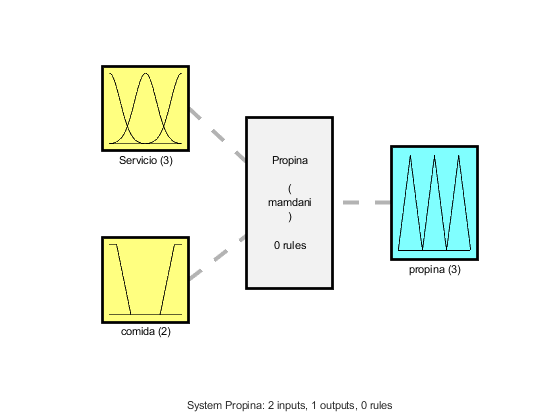

plotfis(fis)

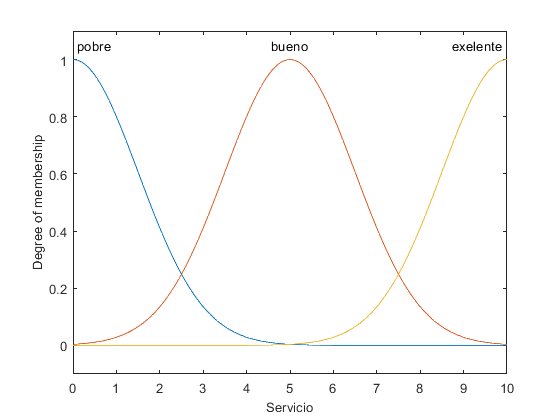

plotmf(fis,'input',1)

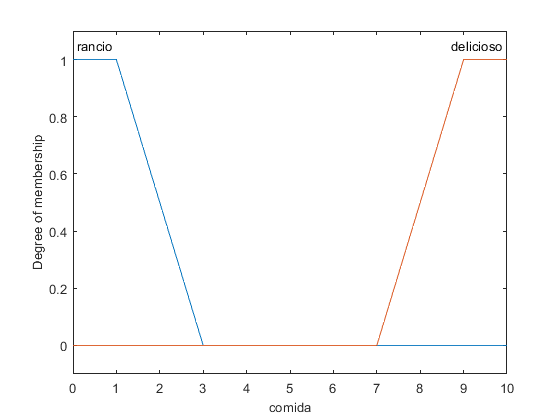

plotmf(fis,'input',2)